# Multiresolution Analysis

*© *Copyright 2022 The MathWorks, Inc

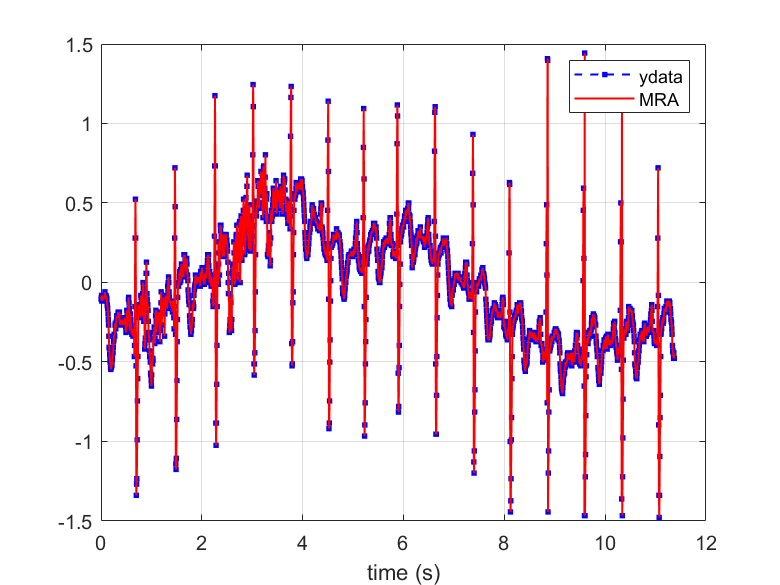

load wecg.mat wecg                      % load ECG signal, sampling frequency 180 Hz
ydata = wecg ;                                    
tdata = (0: numel(ydata) -1)/180;                 % (1 x N) samples , with N = 2048

% DWT and MRA
wname = 'db4 ';                                    % choose Daubechies wavelet db4 
J = 6;                                             % choose resolution J=6

E = modwt(ydata, wname, J);                        % compute Maximal Overlap DWT
mraMatrix = modwtmra(E, wname);                    % compute MRA matrix (J+1)xN 
ydata_mra = sum(mraMatrix);                        % sum down along columns 

% Visualize original and reconstructed signals
figure
plot(tdata, ydata,'b --. ', LineWidth=1, MarkerSize=8);
hold on 
plot(tdata, ydata_mra,'r', LineWidth=1)
legend("ydata", "MRA"), xlabel("time (s)")
grid on

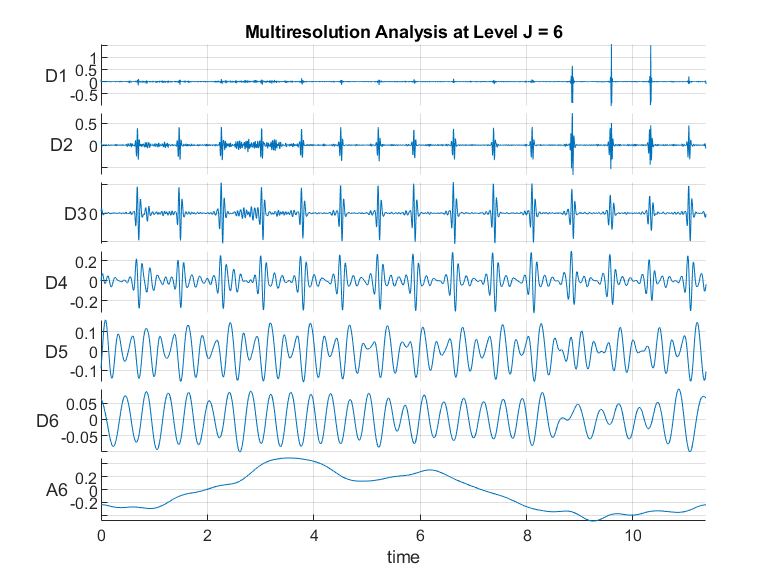


% Visualize decomposition
alldata = [tdata', mraMatrix'];                       % transpose to get Nx(J+2)
T = array2table(alldata , VariableNames=["time","D"+ (1:J),"A"+J]);
figure
stackedplot (T, "XVariable", 1)                       % plot J details and approximation
title("Multiresolution Analysis at Level J = "+J)
grid on

## signalMultiresolutionAnalyzer app

signalMultiresolutionAnalyzer(ydata)